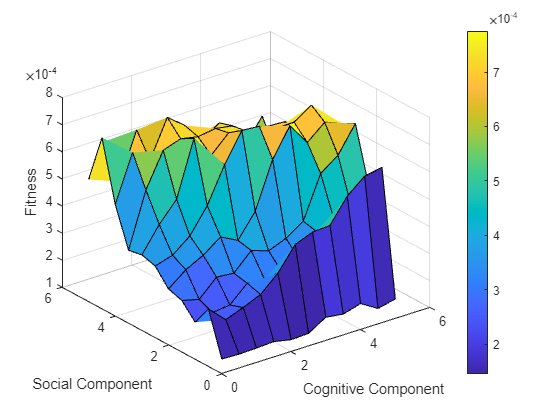

% swarm optimisation algorithm to focus light through turbid media
%clear;
frostedGlass = transmissionMatrix(20, 20);

%averageFitness = fitnessAgainstIterations(1000, 10, 100, 1, 1, 20, 20, 5, frostedGlass);
%[~,~,fitness, iterationsToConverge, careTaker] = swarmOptimiser(-1, 20, 2, 2, 20, 20, 0.1, frostedGlass, [-1,1], [-50, 50]);
%weight = weightAgainstConvergance(0.01:0.005:0.05, 10, 30, 2, 2, 20, 20, frostedGlass);
[convergance, fitness] = SocialCognitivePlot(0:0.5:5, 0:0.5:5, 20, 10, 20, 20, 0.1, frostedGlass);
[xCoords, yCoords] = meshgrid(0:0.5:5, 0:0.5:5);
surf(xCoords, yCoords, fitness)
colorbar
xlabel("Cognitive Component")
ylabel("Social Component")
zlabel("Fitness")

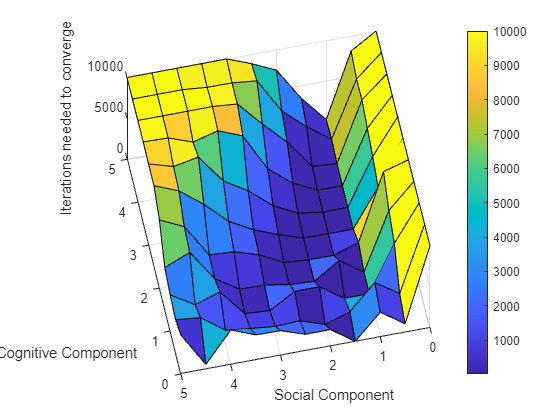


surf(xCoords, yCoords, convergance)
colorbar
xlabel("Cognitive Component")
ylabel("Social Component")
zlabel("Iterations needed to converge")


%scatter(0.01:0.005:0.05, metric)
% set(gca, 'YScale', 'log')
% xlabel("Weight")
% ylabel("Iterations to converge")
% title("Weight against convergance")
% 
% electricField = exp(2*pi*1i*careTaker.swarmBestPosition);
% opticalIntensity = abs((electricField * frostedGlass)).^2;
% heatmap(opticalIntensity)